clear all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Exercise set 3 (Fourier I)         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PARAMETERS

imname = 'cameraman.tif';

tophat_radius = 15.;

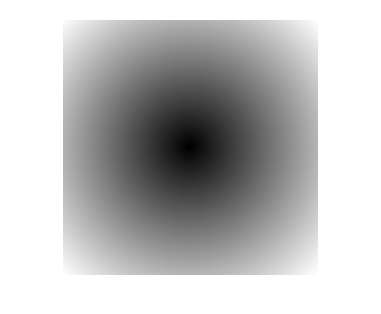

% EX 2
% 2D tophat function in Matlab

tophat = uint8( zeros(255, 255) );

tophat(127, 127) = 1;

Idist = bwdist(tophat);

imshow(Idist, [])

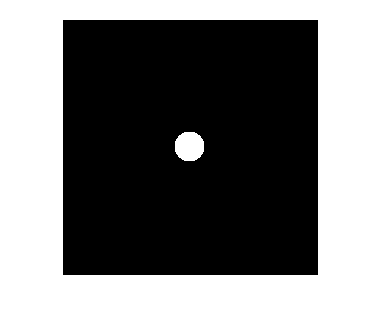


tophat(Idist >= tophat_radius)  = 0;
tophat(Idist <  tophat_radius)  = 1;

imshow(tophat, [])

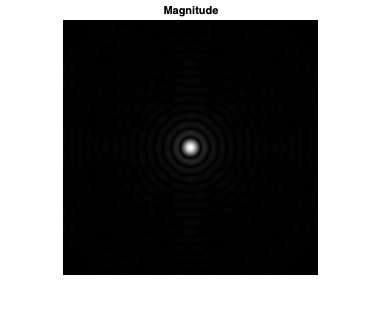


F_tophat = fftshift( fft2(tophat) );

imshow( abs(  F_tophat), [])
title("Magnitude")

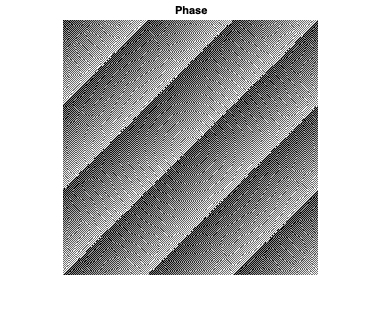

imshow( angle(F_tophat), [])
title("Phase")

%3 Same with a box-shaped tophat filter.

% 2D box-shaped tophat 

tophat_box = uint8( zeros(255, 255) );

tophat_box(127-tophat_radius/2:127+tophat_radius/2, 127-tophat_radius:127+tophat_radius) = 1;

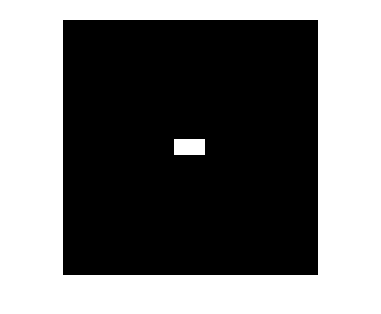


imshow(tophat_box, [])

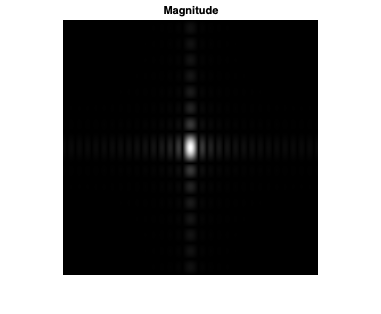


F_tophat_box = fftshift( fft2(tophat_box) );

imshow( abs(  F_tophat_box), [])
title("Magnitude")

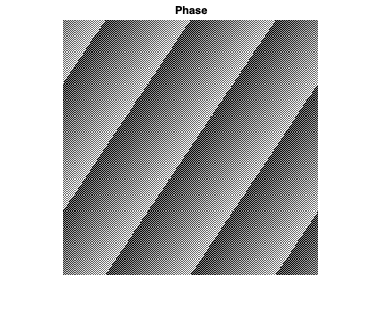

imshow( angle(F_tophat_box), [])
title("Phase")

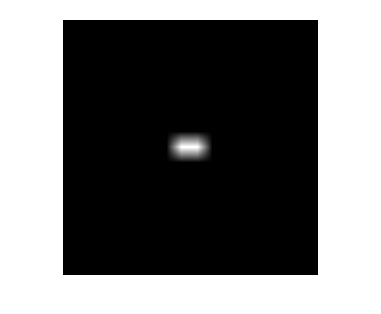


% Smoothed tophat

filter = fspecial("average", 15);

tophat_box_sm = filter2(filter, tophat_box);

imshow(tophat_box_sm)

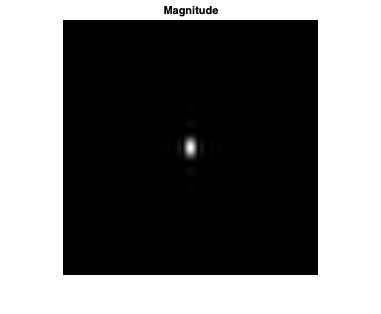


F_tophat_box_sm = fftshift( fft2(tophat_box_sm) );

imshow( abs(  F_tophat_box_sm), [])
title("Magnitude")

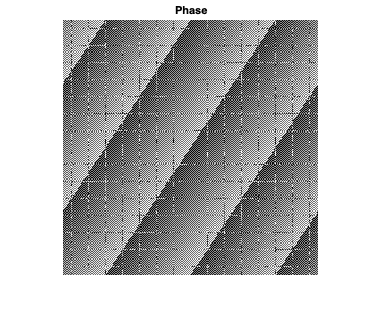

imshow( angle(F_tophat_box_sm), [])
title("Phase")


% Sine wave (playing around...)

%I = zeros(255, 255);  

%numperiods = 30;
%amplitude  = 10;

%x = 1:0.25:size(I, 2); 
%y = sin(x*2*pi/size(I, 2)*numperiods)*amplitude + 127;

%I(sub2ind(size(I), round(y), round(x))) = 1;
%imshow(I);

%imshow(tophat_sine, [])

%F_I = fftshift( fft2(I) );
%imshow( abs(  F_I), [])
%title("Magnitude")
%imshow( angle(F_I), [])
%title("Phase")




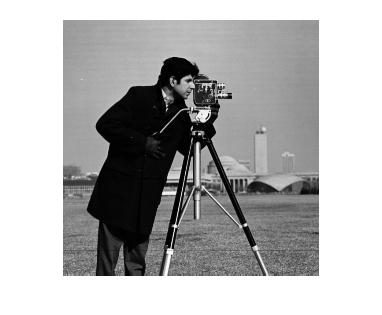


% EX 4 
% Display basic fft and resconstructions

I = imread(imname);

imshow(I, []);

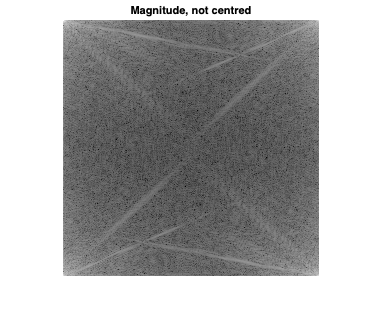


% FFT
% NOTE: fftshift() and ifftshift(); fftshift() does not uniquely inverse
% itself. ifftshift() inverses fftshift. This is linked to how Matlab deals
% with even/odd sized arrays.

F_I = fft2(I);

F_I_mag   = abs(         F_I);
F_I_phase = exp(1i*angle(F_I));

imshow( log(F_I_mag), [] );
title("Magnitude, not centred")

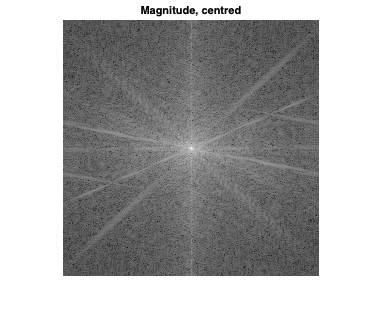


imshow( log(fftshift(F_I_mag)), [] );
title("Magnitude, centred")


imshow( log(F_I_phase), [] );

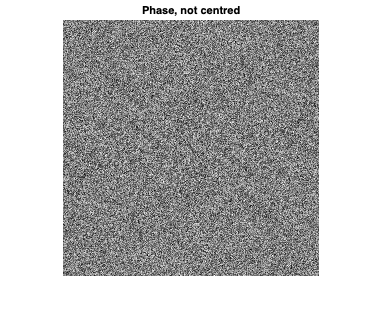

title("Phase, not centred")


imshow( log(fftshift(F_I_phase)), [] );

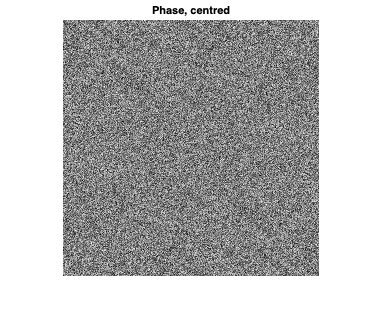

title("Phase, centred")

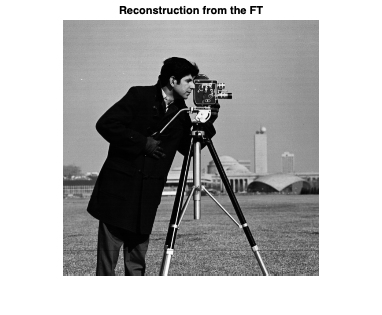


% Reconstruct

I_rec = ifft2( F_I );

I_mag   =  uint8( ifft2( F_I_mag ) );

I_phase =         ifft2(F_I_phase)  ;

% Plot

imshow( I_rec, [] );
title("Reconstruction from the FT")

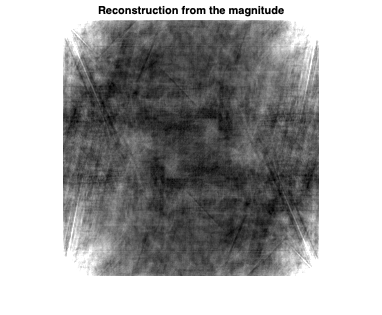


imshow( I_mag   , []);
title("Reconstruction from the magnitude")


imshow( I_phase , []);

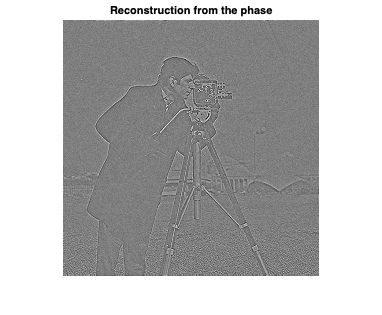

title("Reconstruction from the phase")